Your assignment question:

- Using the **modulate ()** function, generate the frequency modulated output. Following inputs to be considered

- Carrier frequency fc = 10KHz

- Sampling Frequency fs = 23KHz

-  Modulating signal frequency fm = 500Hz

- Modulation Index =10

Plot the Modulating signal and the modulated signal in time domain

fc=10000;
fs=23000;
fm=500;
MI=10;


t = (0:1/fs:0.02)';
x=cos(2*pi*fc*t+MI*sin(2*pi*fm*t));
y = MI*modulate(x,fc,fs,'fm')

y =    -9.1721
   -7.4035
    8.7770
    0.4955
    2.7792
   -8.7285
    8.5484
    7.8451
    7.2303
    9.3525


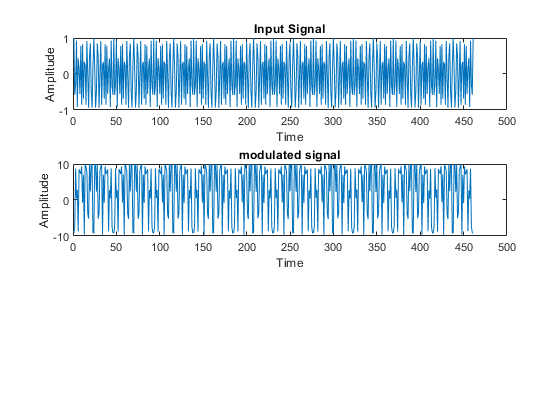


subplot(3,1,1)
plot(x);
title('Input Signal')
xlabel('Time');
ylabel('Amplitude')
subplot(3,1,2)
plot(y);
title('modulated signal')
xlabel('Time');
ylabel('Amplitude')